# Sesion 1: Teoría de errores

### Ejemplo 1

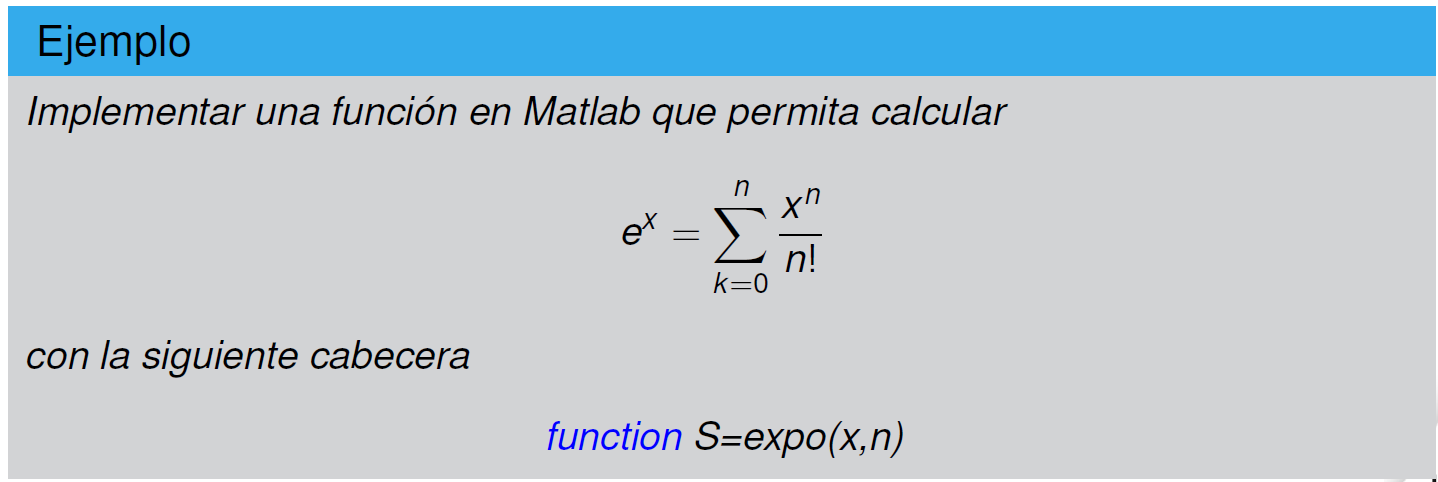


$$e^x = \sum_{k=0}^{n} \frac{x^k}{ k!}$$


format long
x=-5; n=20;
S=expo(x,n)

S =    0.006745540097712


### Ejemplo 2:

format long
valor_real = 6.737947e-3

valor_real =    0.006737947000000


aprox1 = expo(-5,20) % primer caso

aprox1 =    0.006745540097712


aprox2 = 1/expo(5,20) % 20 términos

aprox2 =    0.006737947545483


error_relativo1 = error_rel(valor_real,aprox1)

error_relativo1 =    0.001126915618632


error_relativo2 = error_rel(valor_real,aprox2)

error_relativo2 =      8.095678251195621e-08


### Ejemplo 3

El polinomio de Taylor permite aproximar la función exponencial mediante las sumas:


$$e^x\approx 1+x+\frac{x^2}{2!}+\frac{x^3}{3!}+\ldots+\frac{x^n}{n!}$$


a) Estimar el valor de $e^{-0.5}$ usando 3 términos de la serie anterior. Trabaje con 4 cifras decimales.

a = 1 + (-0.5) + round((-0.5)^2/2,4)

a =    0.625000000000000


a = 1 + (-0.5) + round((-0.5)^2/2,4) + round((-0.5)^3/6,4)

a =    0.604200000000000


b) Considere el valor exacto de $e^{-0.5}= 0.606531$, ¿con cuántos términos el valor estimado tiene un error relativo $\delta_a$ menor que una tolerancia preestablecida $\delta_a^\star$ en tres cifras significativas?

format long
A = 0.606531; % valor exacto 

% usando un control 
% k+1 términos en la aproximación
k=2 

k =      2


a=expo(-0.5,k) % aproximación

a =    0.625000000000000



delta_a=abs(A-a)/abs(A) % error relativo

delta_a =    0.030450216064801


floor( log(5/delta_a)/log(10) ) % cifras significativas

ans =      2


n=2;
delta_a <= 5*10^(-n) % Criterio de cifras significativas

ans = logical
   1


delta_a <= 5*10^(-n-1) % Criterio de cifras significativas

ans = logical
   0


### Ejemplo 4

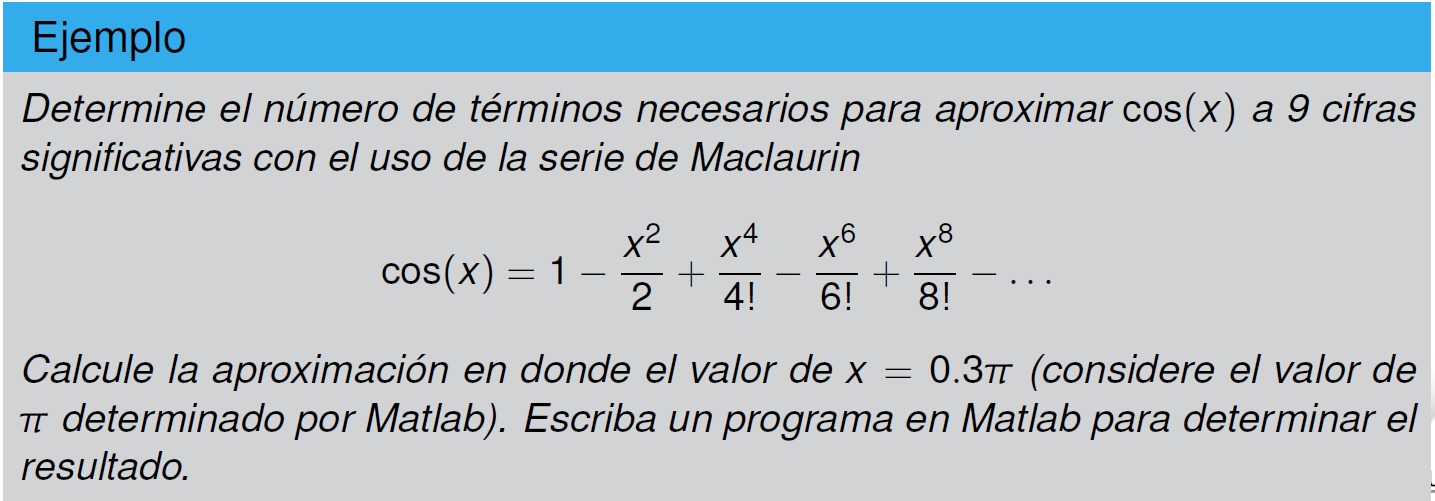

x=0.3*pi;
valor_real = cos(x) 

valor_real = 0.5878

n=4; % cantidad de términos = 5
valor_aprox= fcos(x,n)

valor_aprox = 0.5878

error_relativo = error_rel(valor_real,valor_aprox)

error_relativo = 2.5752e-07

m=7; % número de cifras significativas
if (error_relativo <= 5*10^(-m))
    fprintf('Hay %d cifras significativas',m)
end

Hay 7 cifras significativas

Comprobar que con 6 términos en la aproximación (`n=5`) dicha aproximación tiene 9 cifras significativas (`m=9`).

### Ejercicio (Solución)

Determine el menor número de términos necesarios para que en la aproximación dada por

                        
$$e^{A}=\sum_{n=0}^{\infty} \frac{1}{n !} A^{n},$$


donde 


$$A=\left[\begin{array}{ccc}
0.2 & 5 & -0.1 \\
0 & 0.2 & -0.3 \\
0.02 & 0 & 0.5
\end{array}\right],$$


cada elemento tenga 8 o más cifras significativas. Utilizar el comando de Matlab `expm` para hallar la sumatoria como el valor exacto.

Además, halle el elemento de la matriz aproximada con mayor error relativo porcentual. ¿Piensa que es necesario adaptar la noción de errores al mundo de las matrices?

format short

% Definir la matriz A
A = [0.2 5 -0.1; 
     0 0.2 -0.3; 
     0.02 0 0.5]

Xe=expm(A); % valor exacto
Tol = 5*10^(-8) % 8 cifras significativas

% Aproximando con 1 término
n=0; % contador
Xa=expo(A,n); % valor aproximado
E = abs(Xe-Xa) ./ abs(Xe);


A =     0.2000    5.0000   -0.1000
         0    0.2000   -0.3000
    0.0200         0    0.5000


% Aproximando con más términos 
while ( max(E(:)) > Tol )
    n=n+1;

Tol = 5.0000e-08

    Xa=expo(A,n); 
    E = abs(Xe-Xa) ./ abs(Xe);
end
n=n+1; % cantidad de términos
fprintf('Cantidad de términos para que cada elemento de la aproximación tenga 8 o más cifras significativas: %d', n)
format long

100*E % errores relativos porcentuales
[error_max,ind_error_max]=max(100*E(:));
error_max % mayor error relativo porcentual
ind_error_max % indice lineal con mayor valor de 100*E
fprintf('Elemento de la aproximación de e^A (10 términos) con mayor error relativo porcentual: %.8f', Xa(ind_error_max))
fprintf('Elemento del valor exacto de e^A con mayor error relativo porcentual: %.8f', Xe(ind_error_max))

**En general es más práctico generalizar las nociones de errores desde valores numéricos a vectores o matrices**

Funciones de usuario:

function delta=error_rel(valor_exacto,valor_aprox)

Cantidad de términos para que cada elemento de la aproximación tenga 8 o más cifras significativas: 10

% Doc de la función (ejercicio)

% el símbolo ; es para que no imprima en consola

ans = 1.0e-06 *

   0.009855657048862   0.020007220300891   0.411269460753088
   0.457383617784516   0.009335511826454   0.082392810461242
   0.082392808834910   0.457383652845600   0.014141857623612


delta = abs(valor_exacto-valor_aprox) / abs(valor_exacto);
end

error_max =      4.573836528456000e-07


ind_error_max =      6


function S=expo(x,n)

Elemento de la aproximación de e^A (10 términos) con mayor error relativo porcentual: 0.06761881

% Doc

Elemento del valor exacto de e^A con mayor error relativo porcentual: 0.06761881


% S=e^x
S=0;
for k=0:n
    % término k-ésimo
    t_k = x^k/factorial(k);
    % agregando en S
    S = S + t_k;
end
end

function S=fcos(x,n)
% S=FCOS(x,n) devuelve el coseno de x basado en la serie
% cos(x) = 1-x^2/2+x^4/4!-x^6/6!+x^8/8!+...
% Aquí n+1 indica el número de términos empleados.
%
% Ejemplo:
% >> fcos(2,4)

% S=cos(x)
S=0;
for k=0:n
    % término k-ésimo
    t_k = (-1)^k * x^(2*k)/factorial(2*k);
    % agregando en S
    S = S + t_k;
end

end